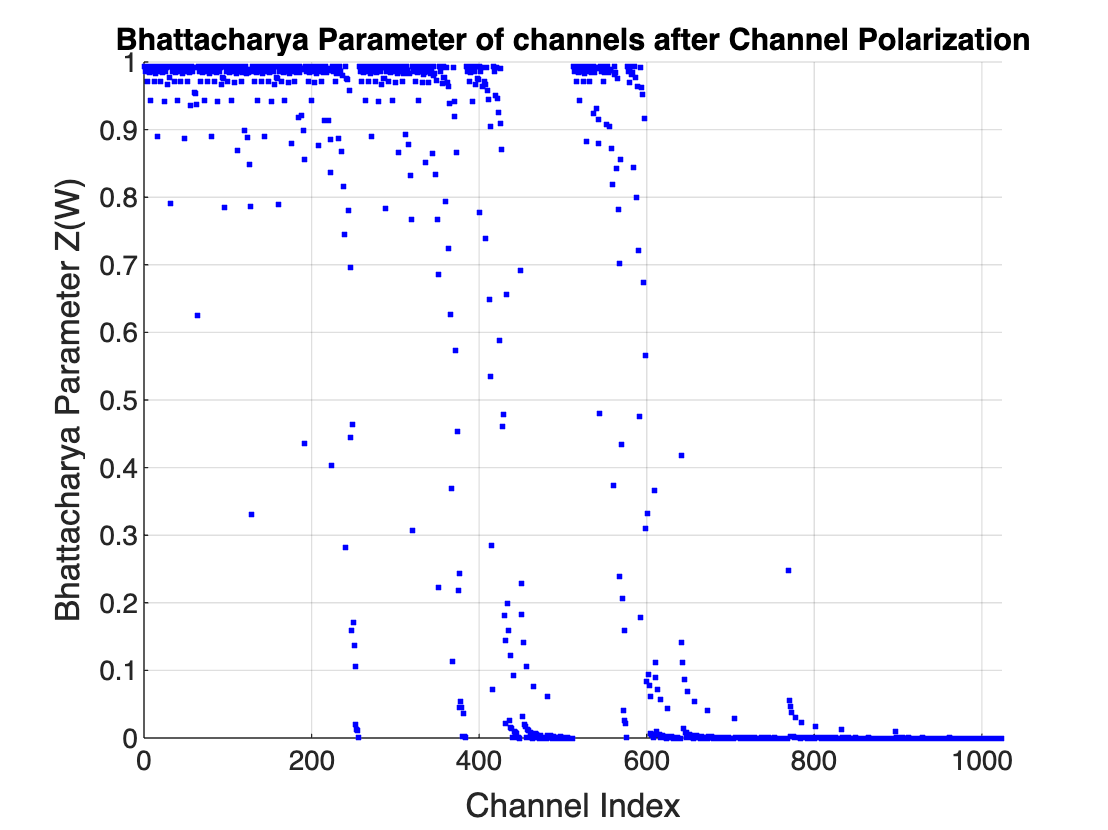

% Parameters
% Parameters
N = 1024; % Block length
SNR_dB = -1; % small change from -5 dB
SNR = 10^(SNR_dB/10);
sigma2 = 1/(2*SNR);

% Initialize arrays
m = zeros(1, N);
Z = zeros(1, N);

% Initial mean LLR
m(1) = 2 / sigma2;

% Recursive calculation of mean LLR
for lev = 1:log2(N)
    half = 2^(lev-1);
    for i = half:-1:1
        m(2*i-1) = inv_f(1 - (1 - f(m(i)))^2);  % first child
        m(2*i) = 2 * m(i);                      % second child
    end
end

% Calculate Bhattacharya parameters
for i = 1:N
    Z(i) = exp(-m(i)/4);
end

% --- Plotting the graphs ---

figure;
% subplot(2,1,1);
scatter(1:N, Z, 'b.');
title('Bhattacharya Parameter of channels after Channel Polarization');
xlabel('Channel Index', 'FontSize', 12);
ylabel('Bhattacharya Parameter Z(W)', 'FontSize', 12);
grid on;
ylim([0 1]);
xlim([0 N]);

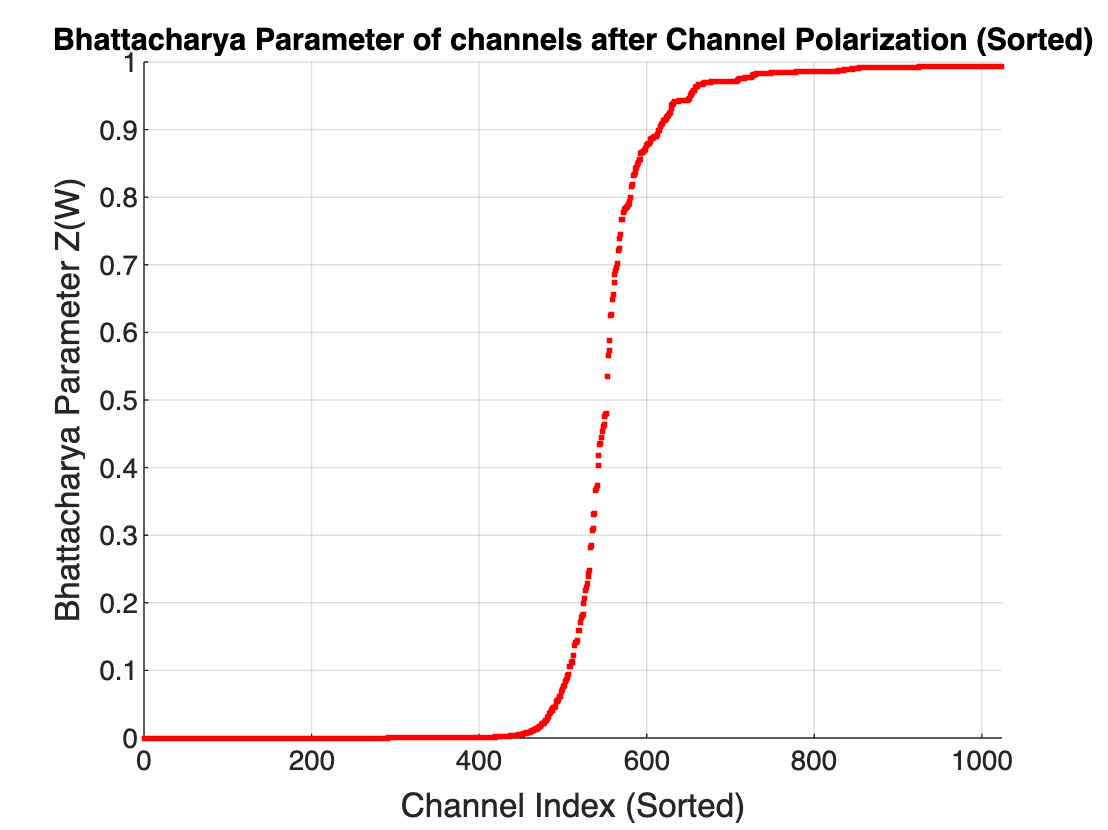


figure;
% subplot(2,1,2);
scatter(1:N, sort(Z), 'r.');
title('Bhattacharya Parameter of channels after Channel Polarization (Sorted)');
xlabel('Channel Index (Sorted)', 'FontSize', 12);
ylabel('Bhattacharya Parameter Z(W)', 'FontSize', 12);
grid on;
ylim([0 1]);
xlim([0 N]);


% --- Helper Functions ---
function y = f(x)
    if x < 10
        alpha = -0.4527;
        beta = 0.0218;
        gamma = 0.86;
        y = exp(alpha * x^gamma + beta);
    else
        y = sqrt(pi/x) * (1 - 10/(7*x)) * exp(-x/4);
    end
end

function x = inv_f(y)
    if y > 0.5
        alpha = -0.4527;
        beta = 0.0218;
        gamma = 0.86;
        x = ((log(y) - beta) / alpha)^(1/gamma);
    else
        x = -4 * log(y);
    end
end

